## Quantizzazione

In questa demo vediamo gli effetti della quantizzazione su di un segnale di parola.

### Definizioni

La quantizzazione consiste nel associare ad ogni intervallo di numeri reali un singolo valore rappresentativo detto livello di quantizzazione. In particolare, ci interessiamo al caso in cui i valori d'ingresso siano compresi in $\left(-A,A\right)$. Tale intervallo è suddiviso in $L$ intervalli. I valori d'ingresso sono rappresentati dal livello associato all'intervallo, ad esempio (ma non necessariamente) il centro dell'intervallo; oppure, il valore più probabile all'interno dell'intervallo stesso.

Un caso molto comune è quello della **quantizzazione uniforme. **Nella quantizzazione uniforme, l'intervallo $\left(-A,A\right)$ è suddiviso in $L$ intervalli uguali di ampiezza $\Delta =\frac{2A}{L}$. Ogni intervallo è rappresentato dal centro dell'intervallo stesso.

È facile verificare che la seguente funzione implementa la quantizzazione uniforme di un intervallo $\left(-A,A\right)$ con $A=n\Delta \;$


$$Q\left(x\right)=\Delta \;\textrm{round}\left(\frac{x}{\Delta \;}\right)$$


La quantizzazione uniforme equivale a prendere il multiplo intero di $\Delta \;$ più vicino a $x$. 

Tale operazione s'implementa facilmente in Matlab: 

qu = @(x,Delta) Delta*round(x/Delta);

Calcoliamo per esempio come viene quantizzato un valore x con diversi valori di $\Delta \;$

x=14;
for Delta = [10:-1:1],
    qx = qu(x,Delta);
    error = x-qx;
    fprintf('Per Delta=%d, Q(%d)=%d. Errore %d\n', ...
        Delta,x,qx,error);
end

Per Delta=10, Q(14)=10. Errore 4
Per Delta=9, Q(14)=18. Errore -4
Per Delta=8, Q(14)=16. Errore -2
Per Delta=7, Q(14)=14. Errore 0
Per Delta=6, Q(14)=12. Errore 2
Per Delta=5, Q(14)=15. Errore -1
Per Delta=4, Q(14)=16. Errore -2
Per Delta=3, Q(14)=15. Errore -1
Per Delta=2, Q(14)=14. Errore 0
Per Delta=1, Q(14)=14. Errore 0


In genere l'errore decresce al decrescere di $\Delta \;$. Si può dimostrare che se l'ingresso ha distribuzione di probabilità uniforme, l'errore è uniformemente distributo in $\left(-\frac{\Delta }{2},\frac{\Delta }{2}\right)$, con valore quadratico medio pari a $\frac{\Delta^2 }{12}$ .

Vediamo anche come vengono quantizzati i valori di $x\in \left(-A,A\right)\;$

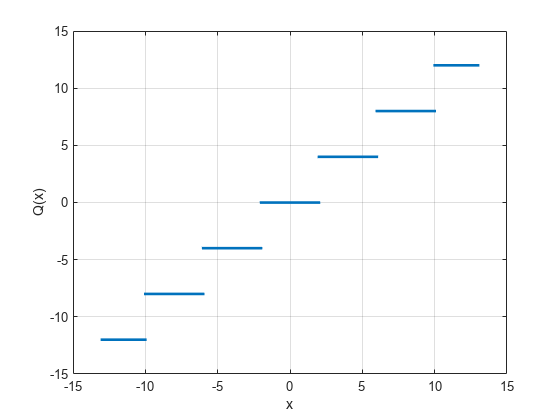

A = 13;
N = 1e4;
Delta = 4;
x = linspace(-A,A,N); % N punti equispaziati tra -A ed A
figure; 
plot(x,qu(x,Delta), '.'); grid; xlabel ('x')'; ylabel('Q(x)')

A volte si preferisce usare come parametro $L$ invece di $\Delta \;,$ o ancora il numero di bit per campione quantizzato, $R=\log_2 L$

### Applicazione al segnale di voce

Cancelliamo tutte le variabili in memoria e chiudiamo eventuali figure

clear variables
close all

#### Caricamento

Qui si carica e si ascolta la traccia audio. Se si vuole registrare una nuova traccia, usare `recordVoice.mlx`

namefile='myvoicerecording16kHz.mat';
load(namefile,'Fc','y','N')
% Periodo di campionamento
Tc = 1/Fc;
% numero di campioni nella traccia
M = length(y);
% intervallo temporale della traccia
t =(0:M-1)*Tc;
% Ampiezza del segnale 
A=max(abs(y)); 

% Riproduzione della traccia audio registrata
h=msgbox('Segnale vocale'); 
yp=audioplayer(y,Fc);
play(yp)
waitfor(h);

Ora scegliamo il numero di bit di quantizzazione

R = 5;

Il segnale sarà quantizzato su $L=2^R$ livelli. L'intervallo di quantizzazione è $\Delta =\frac{2A}{2^R }={A\cdot \;2}^{-R+1}$

qu = @(x,Delta) Delta*round(x/Delta);
Delta = A*2^(1-R);    
yq = qu(y,Delta);

Ascoltiamo il segnale quantizzato:

msg = sprintf('Segnale vocale quantizzato su %d bit',R);
h=msgbox(msg); 
yp=audioplayer(yq,Fc);
play(yp)
waitfor(h);

Tracciamo l'andamento di $y\;$e $Q\left(y\right)$. Facciamo uno zoom su di un intervallo per apprezzare l'effetto della quantizzazione

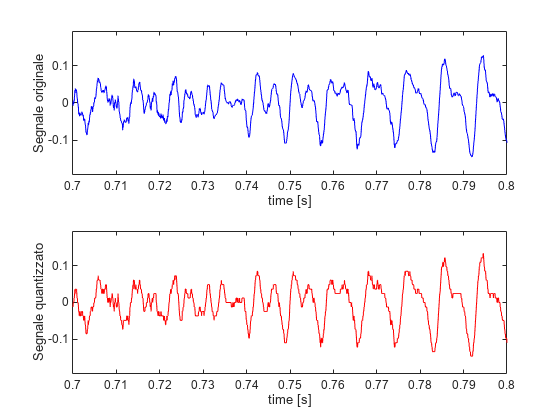

figure; 
subplot(211)
plot(t,y,'b');
xlabel('time [s]')
ylabel('Segnale originale')
xlim([0.7,0.8]); ylim([-A,A]);
subplot(212)
plot(t,yq,'r-');
xlim([0.7,0.8]); ylim([-A,A]);
xlabel('time [s]')
ylabel('Segnale quantizzato')

Tracciamo l'errore di quantizzazione $y,Q\left(y\right),\epsilon =y-Q\left(y\right)$. Facciamo uno zoom su di un intervallo di un centesimo di secondo. Notare l'ampiezza dell'errore compresa tra $-\frac{\Delta }{2}$ e $\frac{\Delta }{2}$

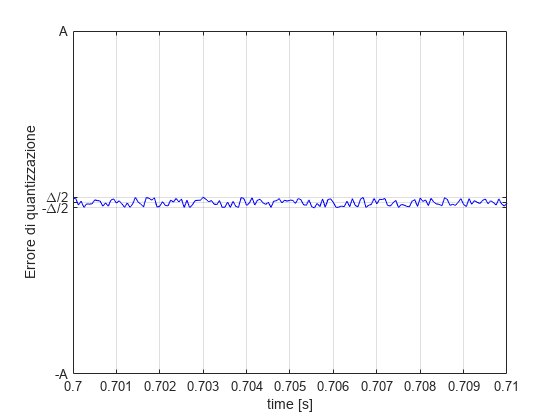

figure
h=plot(t,y-yq,'b');
xlim([0.7,0.71]); ylim([-A,A]);
set(gca,'YTick',[-A,-Delta/2,0,Delta/2,A], ...
    'YTickLabel',{'-A', '-\Delta/2', '' , '\Delta/2', 'A'});
grid
xlabel('time [s]')
ylabel('Errore di quantizzazione')

Vediamo ora l'impatto sugli spettri di ampiezza

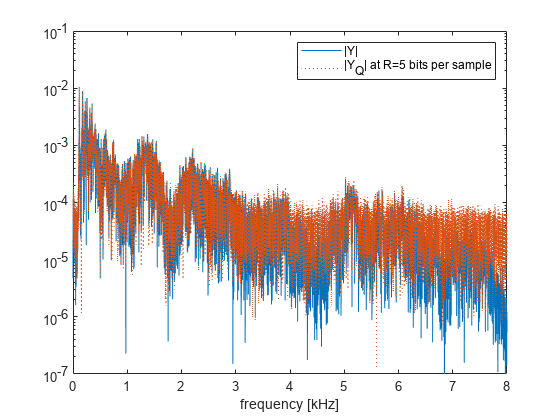

[Y, F]= CTFT_real(y,Fc);
[Yq, Fq]= CTFT_real(yq,Fc);

figure; 
semilogy(F/1e3,Y,Fq/1e3,Yq, ':');  
ylim([1e-7,1e-1]);
xlabel('frequency [kHz]')
legend('|Y|',['|Y_Q| at R=',num2str(R),' bits per sample'])
xlabel('frequency [kHz]')

Osserviamo che lo spettro del segnale quantizzato differisce da quello del segnale originario per avere valori relativamente grandi ad alta frequenza. Per studiare meglio il fenomeno, tracciamo lo spettro dell'errore di quantizzazione.

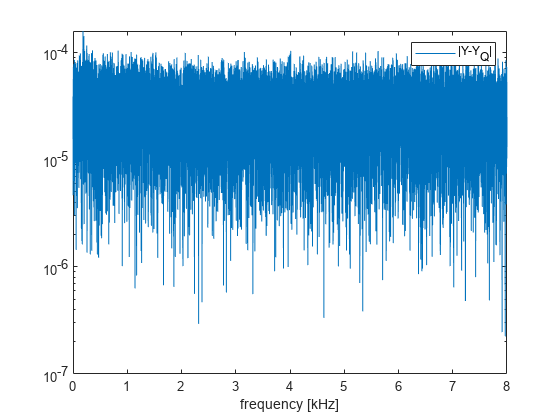

[QN, F]= CTFT_real(y-yq,Fc);

figure; 
semilogy(F/1e3,QN);  

xlabel('frequency [kHz]')
legend('|Y-Y_Q|')
xlabel('frequency [kHz]')

Si parla di **rumore bianco** perché è presente a tutte le frequenze con ampiezza approssimativamente costante.